# Read or Skip Quoted Text and Numeric Fields

Read the first and last columns of data from a text file. Skip a column of text and a column of integer data.

Load the file `names.txt` and preview its contents in a text editor. A screen shot is shown below. Notice that the file contains two columns of quoted text, followed by a column of integers, and finally a column of floating point numbers.

filename = 'names.txt';

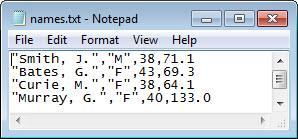

Read the first and last columns of data in the file. Use the conversion specifier, `%q` to read the text enclosed by double quotation marks (`"`). `%*q` skips the quoted text, `%*d` skips the integer field, and `%f` reads the floating-point number. Specify the comma delimiter using the `'Delimiter'` name-value pair argument.

fileID = fopen(filename,'r');
C = textscan(fileID,'%q %*q %*d %f','Delimiter',',');
fclose(fileID);

Display the output. `textscan` returns a cell array `C` where the double quotation marks enclosing the text are removed.

celldisp(C)

*Copyright 2012 The MathWorks, Inc.*